## Importing the data

read the 3 tables csv files containing data from the start of the operation to the end

dataP1 = readtable("C:\Users\user\Documents\MSc(Eng) UCT\DATA\SWaT.A1 & A2_Dec 2015-20210712T014737Z-001\SWaT.A1 _ A2_Dec 2015\Physical\SWaT_Dataset_Normal_v0.xlsx");

dataP2 = readtable("C:\Users\user\Documents\MSc(Eng) UCT\DATA\SWaT.A1 & A2_Dec 2015-20210712T014737Z-001\SWaT.A1 _ A2_Dec 2015\Physical\SWaT_Dataset_Normal_v1.xlsx");

dataP3= readtable("C:\Users\user\Documents\MSc(Eng) UCT\DATA\SWaT.A1 & A2_Dec 2015-20210712T014737Z-002\SWaT.A1 _ A2_Dec 2015\Physical\SWaT_Dataset_Attack_v0.xlsx");

Concatenate tables

df = [dataP1;dataP2;dataP3];

Convert Timestamp column to datetime

df.Timestamp = datetime(df.Timestamp);

Convert response column to categorical

df.Normal_Attack = categorical(df.Normal_Attack);

Since system takes 6 hours to stabilise, initially 7 hours of data is removed

% Before it is removed, lets plot a few features to see the instability
%---plot(df.LIT101);
% Remove 7 hours of initial data

a = df.Timestamp(1) + hours(7);
 idx = df.Timestamp > (a - seconds(1));
 df = df(idx,:);

Changing pump data from 1 and 2 to logical 0 or 1

df.P101 = df.P101 - 1;df.P102 = df.P102 - 1;df.P201 = df.P201 - 1;df.P202 = df.P202 - 1;df.P203 = df.P203 - 1;df.P204 = df.P204 - 1;
df.P205 = df.P205 - 1;df.P206 = df.P206 - 1;df.P301 = df.P301 - 1;df.P302 = df.P302 - 1;df.P401 = df.P401 - 1;df.P402 = df.P402 - 1;
df.P403 = df.P403 - 1;df.P404 = df.P404 - 1;df.P501 = df.P501 - 1;df.P502 = df.P502 - 1;df.P601 = df.P601 - 1;
df.P602 = df.P602 - 1;

Merging backup pump data to main pump data

df.P101 = mergePumps(df.P101,df.P102); 
df.P201 = mergePumps(df.P201,df.P202);
df.P203 = mergePumps(df.P203,df.P204);
df.P205 = mergePumps(df.P205,df.P206);
df.P302 = mergePumps(df.P302,df.P301);
df.P402 = mergePumps(df.P402,df.P401);
df.P403 = mergePumps(df.P403,df.P404);
df.P501 = mergePumps(df.P501,df.P502); 

Drop backup pumps from dataset

df = removevars(df,{'P102','P202','P204','P206','P301','P401','P404','P502','P603'});

Number of each instance in response column

summary(df.Normal_Attack)

     A ttack           37 
     Attack         54584 
     Normal       1338498 


Attack is mispelled 37 times and needs to be replaced be corrected

df.Normal_Attack = mergecats(df.Normal_Attack,"A ttack","Attack");

Number of each instance in response column

summary(df.Normal_Attack)

     Attack        54621 
     Normal      1338498 


Create logical array of response vector where attack is a high

attacks = df.Normal_Attack == "Attack";

Plot of attacks

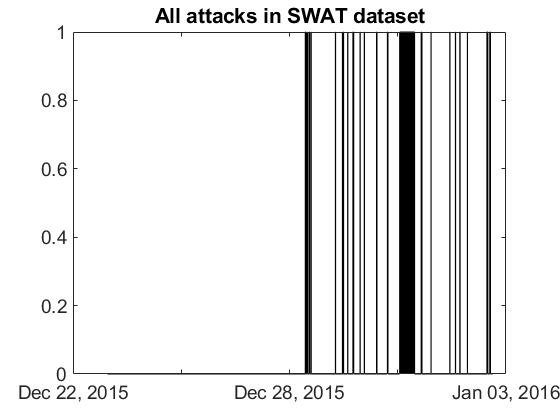

%all attacks
area(df.Timestamp ,attacks,'FaceColor', 'k')
title('All attacks in SWAT dataset','FontSize',24)
set(gca,'fontsize',14)

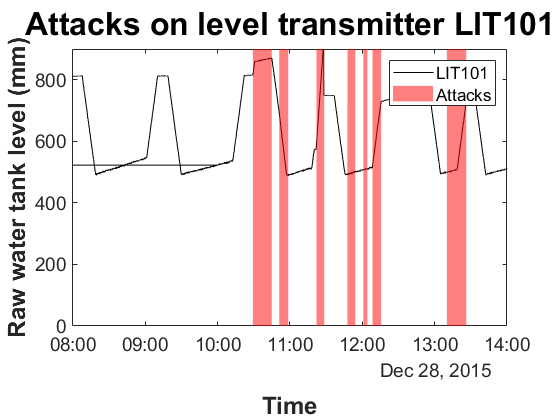


%LIT101 - Single Stage Single Point Attack
plotAgainstAttacks(df,df.LIT101)
title('Attacks on level transmitter LIT101','FontSize',24)
xlabel({'';'Time'},'FontWeight','bold','FontSize',18)
ylabel('Raw water tank level (mm)','FontWeight','bold','FontSize',18)
xlim([datetime('28-Dec-2015 08:00:00'),datetime('28-Dec-2015 14:00:00')])
ylim([0 900])
legend('LIT101','Attacks')

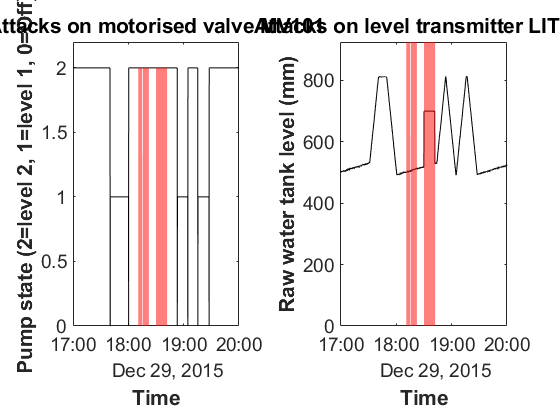

% MV-101, LIT-101 - Single Stage Multi Point Attack
tiledlayout(1,2);
nexttile % Tile 1
plotAgainstAttacks(df,df.MV101)
title('Attacks on motorised valve MV101')
xlabel({'';'Time'},'FontWeight','bold')
ylabel('Pump state (2=level 2, 1=level 1, 0=Off)','FontWeight','bold')
xlim([datetime('29-Dec-2015 17:00:00'),datetime('29-Dec-2015 20:00:00')])
ylim([0 2.2])
nexttile % Tile 2
plotAgainstAttacks(df,df.LIT101)
title('Attacks on level transmitter LIT101')
xlabel({'';'Time'},'FontWeight','bold')
ylabel('Raw water tank level (mm)','FontWeight','bold')
ylim([0 925])
xlim([datetime('29-Dec-2015 17:00:00'),datetime('29-Dec-2015 20:00:00')])

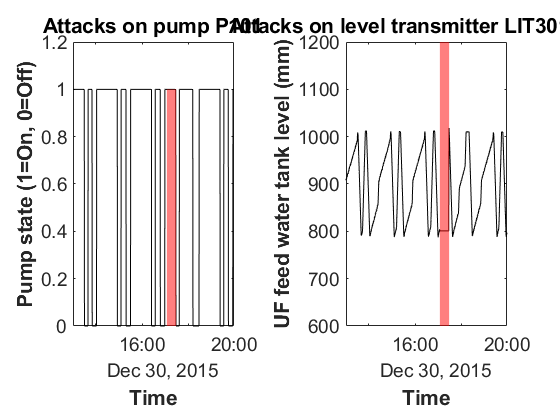

%P-101, LIT-301 - Multi Stage Single Point Attacks
tiledlayout(1,2);
nexttile % Tile 1
plotAgainstAttacks(df,df.P101)
title('Attacks on pump P101')
xlabel({'';'Time'},'FontWeight','bold')
ylabel('Pump state (1=On, 0=Off)','FontWeight','bold')
xlim([datetime('30-Dec-2015 13:00:00'),datetime('30-Dec-2015 20:00:00')])
ylim([0 1.2])
nexttile % Tile 2
plotAgainstAttacks(df,df.LIT301)
title('Attacks on level transmitter LIT301 (mm)')
xlabel({'';'Time'},'FontWeight','bold')
ylabel('UF feed water tank level (mm)','FontWeight','bold')
ylim([600 1200])
xlim([datetime('30-Dec-2015 13:00:00'),datetime('30-Dec-2015 20:00:00')])

%UV-401, AIT-502, P-501 - Multi Stage Multi Point Attacks
df.UV401 = df.UV401 - 1; %only run once

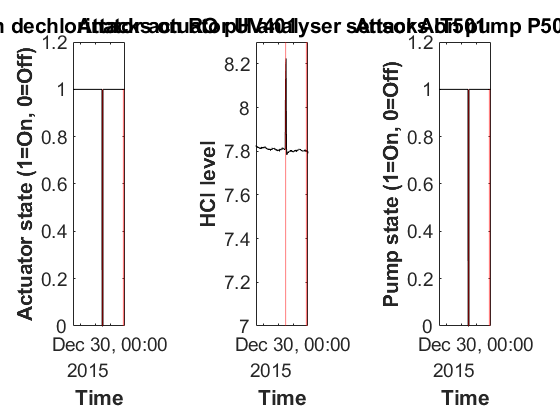

tiledlayout(1,3);
nexttile % Tile 1
plotAgainstAttacks(df,df.UV401)
title('Attacks on dechlorinator actuator UV401')
xlabel({'';'Time'},'FontWeight','bold')
ylabel('Actuator state (1=On, 0=Off)','FontWeight','bold')
xlim([datetime('29-Dec-2015 19:00:00'),datetime('30-Dec-2015 02:00:00')])
ylim([0 1.2])
nexttile % Tile 2
plotAgainstAttacks(df,df.AIT501)
title('Attacks on RO pH analyser sensor AIT501')
xlabel({'';'Time'},'FontWeight','bold')
ylabel('HCl level','FontWeight','bold')
xlim([datetime('29-Dec-2015 19:00:00'),datetime('30-Dec-2015 02:00:00')])
ylim([7 8.3])
nexttile % Tile 3
plotAgainstAttacks(df,df.P501)
title('Attacks on pump P501')
xlabel({'';'Time'},'FontWeight','bold')
ylabel('Pump state (1=On, 0=Off)','FontWeight','bold')
xlim([datetime('29-Dec-2015 19:00:00'),datetime('30-Dec-2015 02:00:00')])
ylim([0 1.2])

Dealing with backup pumps

summary(categorical(df.P205))

     0      433331 
     1      959788 


summary(categorical(df.P206))

     0      1393064 
     1           55 


pidx = df.P205 == 0 & df.P206 ==1;
nnz(pidx)

ans = 0

## Data visualisation and understanding

### Correlation Matrix

Correlation matrices will tell us how closely related variables are.

High correlation is given by values less than -0.8 and greater than 0.8

#### Stage P1: Raw water supply & storage

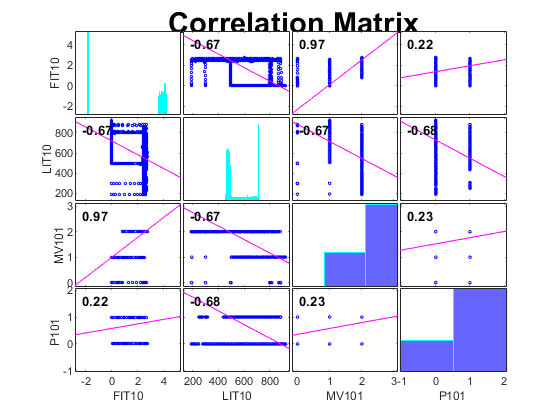

corrplot(df(:,2:5))
set(gca,'DefaultTextFontSize',30,'FontSize',20)

Observations:

- FIT101 measuring flow into raw water tank is highly correlated to MV101 which controls water flow to the raw water tank.

- LIT101 and MV101 which measure the raw water tank level share a negative correlation since they share an inversely proportinal relationship.

- LIT101 and P101 which pumps water from raw water tank  share a negative correlation since they share an inversely proportinal relationship. 

Features to be dropped:

- MV101 since it is actuator data and not much processing can be done on it.

#### Stage P2: Chemical dosing

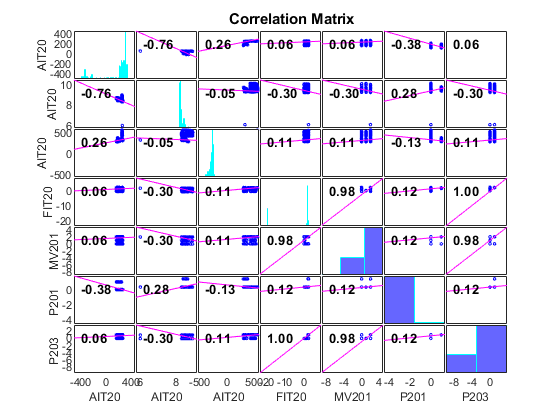

corrplot(df(:,["AIT201","AIT202","AIT203","FIT201","MV201","P201","P203"]))

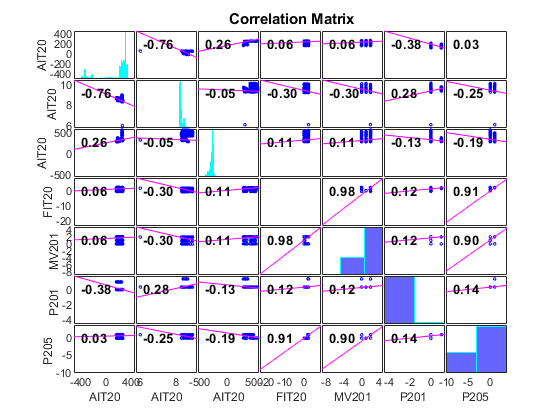

%error observed adding 7 varriables to correlation plot. 3 plots will
%are generated as a solution to check correlation between all variables
corrplot(df(:,["AIT201","AIT202","AIT203","FIT201","MV201","P201","P205"]))

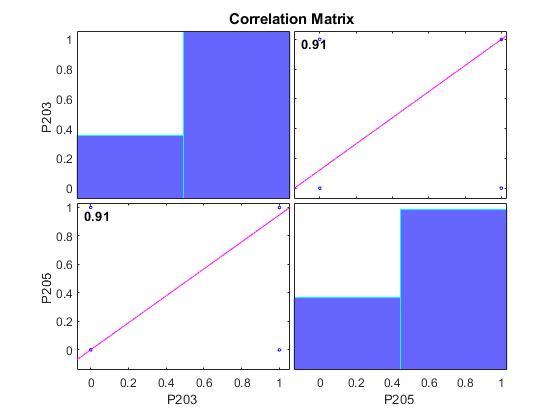

corrplot(df(:,["P203","P205"]))

Observations: NB. Explain the dissertation

- AIT201 and A202 have high correlation but not high enough to be dropped. 

- MV201 is highly correlated to FIT201

- P203 is highly correlated to MV201

- P205 is stringly correlated to 3 features,FIT201, MV201 and P203

Features to be dropped:

- MV201, P205

#### Stage P3: UF

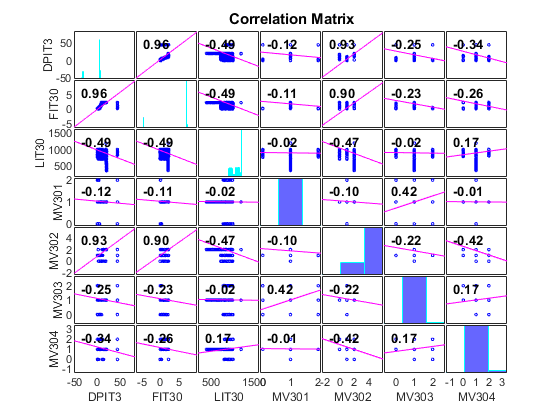

corrplot(df(:,["DPIT301","FIT301","LIT301","MV301","MV302","MV303","MV304"]))

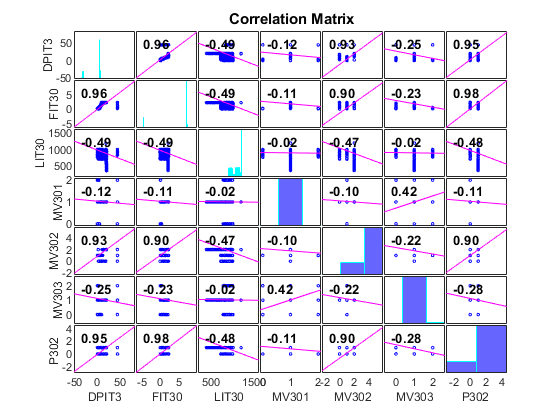

%error observed adding 7 varriables to correlation plot. 3 plots will
%are generated as a solution to check correlation between all variables
corrplot(df(:,["DPIT301","FIT301","LIT301","MV301","MV302","MV303","P302"]))

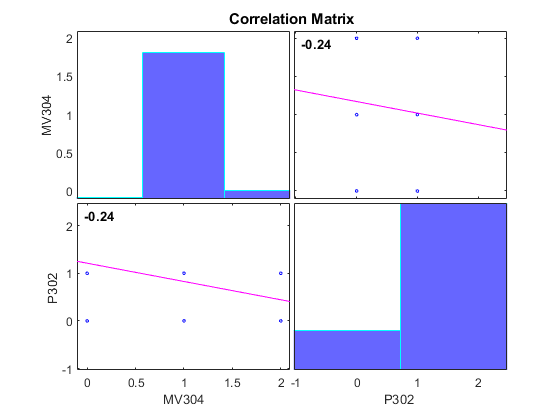

corrplot(df(:,["MV304","P302"]))

Observations: NB. Explain the dissertation, (plot the graphs aswell)

- FIT301 explains the same information as DPIT301,MV302, P302

- FIT301 wont be dropped because it can be processed to extract informative features

Features to be dropped:

- DPIT301 and MV302 

#### Stage P4: Dechlorination

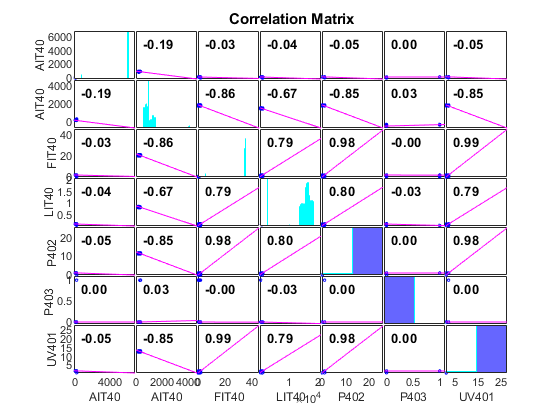

corrplot(df(:,22:28))

Observations: NB. Explain the dissertation, (plot the graphs aswell)

- AIT402, FIT401, P402 and UV401 are closely correlated beacuse they form part of the dechlorination process but not close enough to drop either.

- FIT401 and UV401 are closely correlated because one controls the other.

Features to be dropped:

- P402 and UV401 (AIT402 and FIT201 are not as correlated to each other as with FIT201 with P402 and UV401, in addition these are sensor readings can be further processed)

#### Stage P5: RO

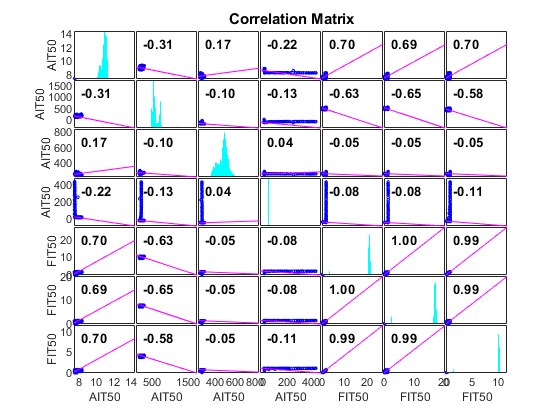

corrplot(df(:,29:35))

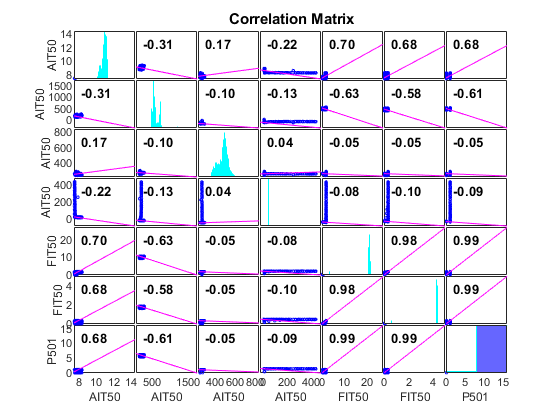

%error observed adding 7 varriables to correlation plot. 
% 
corrplot(df(:,["AIT501","AIT502","AIT503","AIT504","FIT501","FIT504","P501"]))

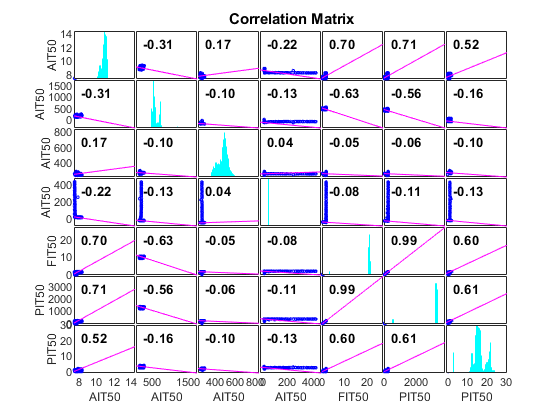


corrplot(df(:,["AIT501","AIT502","AIT503","AIT504","FIT501","PIT501","PIT502"]))

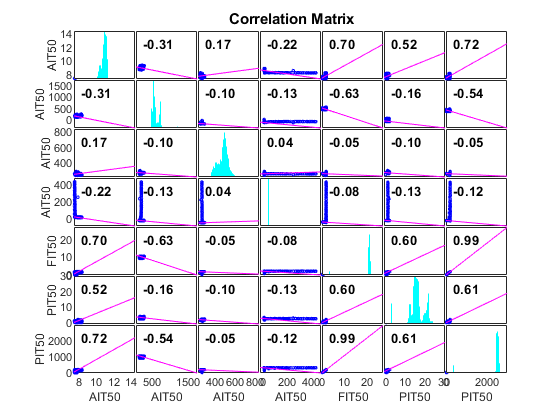

corrplot(df(:,["AIT501","AIT502","AIT503","AIT504","FIT501","PIT502","PIT503"]))

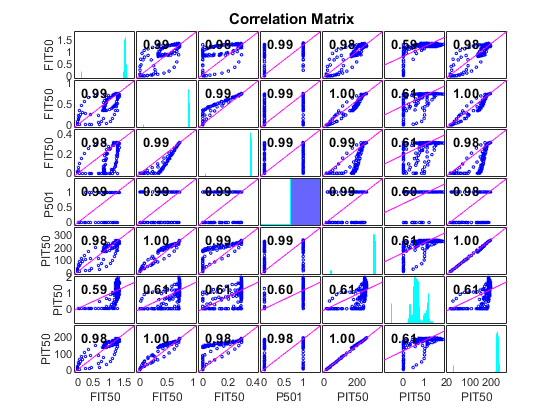

corrplot(df(:,["FIT502","FIT503","FIT504","P501","PIT501","PIT502","PIT503"]))

Observations: NB. Explain the dissertation, (plot the graphs aswell)

-  FIT501,FIT502, FIT503, FIT504, P501, PIT501 and PIT503 are perfactly correlated

Features to be dropped:

- FIT501,FIT502, FIT503, FIT504, P501, PIT501 and PIT503

#### Stage P6: RO permeate transfer, UF backwash

A correlation matrix plot will not be performed since there is only one variable in this stage.

Dropping variables

dfdropped = removevars(df,{'MV101','MV201','P203','P205','DPIT301','MV302','P302','P402','UV401','FIT501','FIT502', 'FIT503', 'FIT504', 'PIT501','PIT503','P601'});

### Baseline Model

Categorical variables

[m,n] = size(dfdropped) ;
P = 0.70 ;
dataTrain = dfdropped(1:round(P*m),:) ;
dataTest = dfdropped(round(P*m)+1:end,:) ;


yfit=trainedQDModel.predictFcn(dataTest);
NormalAttackBinary = dataTest.Normal_Attack;

% Convert Normal cat to 0 and Attack to 1 
% Test Data
NormalAttackBinary = grp2idx(NormalAttackBinary);
NormalAttackBinary(NormalAttackBinary == 2) = 0;
% Classification model
yfitBinary = grp2idx(yfit);
yfitBinary(yfitBinary == 2) = 0;

% % plot the attacks
% area(dataTest.Timestamp, NormalAttackBinary,'FaceColor','k')
% hold on
% area(dataTest.Timestamp,yfitBinary,"FaceAlpha", 0.5, "LineStyle", 'none','FaceColor', 'r')
% hold off

% Select only prominent attack
TimestampIndx = dataTest.Timestamp > '31-Dec-2015 01:17:00' & dataTest.Timestamp < '31-Dec-2015 11:15:27';
NormalAttackBinary =NormalAttackBinary.*TimestampIndx;
yfitBinary = yfitBinary.*TimestampIndx;

% plot the attacks
area(dataTest.Timestamp, NormalAttackBinary,'FaceColor','k')
hold on
area(dataTest.Timestamp,yfitBinary,"FaceAlpha", 0.5, "LineStyle", 'none','FaceColor', 'r')
hold off
legend('Test data attacks','Predicted attacks')
ax = gca; ax.FontSize = 14;

TTD = NormalAttackBinary - yfitBinary;
TTDs = sum(TTD)
TTDmins = TTDs/60

### Parallel Computing

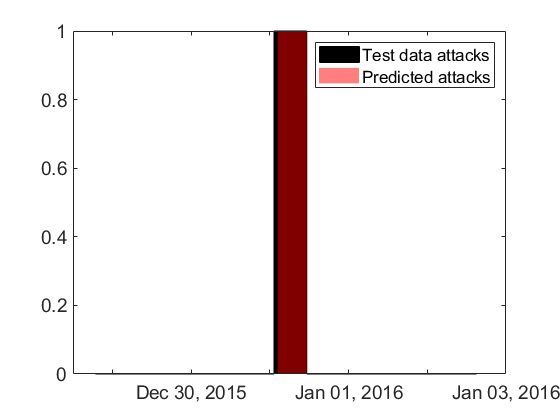

p = gcp;

delete(p)

delete(gcp('nocreate'))

TTDs = 3932

tic

TTDmins = 65.5333

SVMmodel1 = trainSVMClassifier(dataTrain);
toc
parpool

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


tic
SVMmodel2 = trainSVMClassifier(dataTrain);
toc

yfit=treemodel.predictFcn(dataTest);
confusionchart(dataTest.Normal_Attack,yfit)

### Dataset after feature extraction

dfdropped = removevars(dfdropped,{'LIT101','AIT201','AIT202','AIT203','FIT301','LIT301','AIT401','AIT402','FIT401','LIT401','AIT501' ...

Elapsed time is 745.627655 seconds.


    ,'AIT502','AIT503','AIT504','PIT502'});

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).

ans = 

 ProcessPool with properties: 

            Connected: true
           NumWorkers: 4
              Cluster: 

NormalAttack = dfdropped(:,'Normal_Attack');
removevars(dfdropped,{'Normal_Attack'});
dfprocessed = addvars(dfdropped,{'Weekday','Hour','FIT101Filtered','FIT101Peaks',' FIT101Frequencies','LIT101Filtered', 'FIT101Slopes', ...

Elapsed time is 665.981082 seconds.


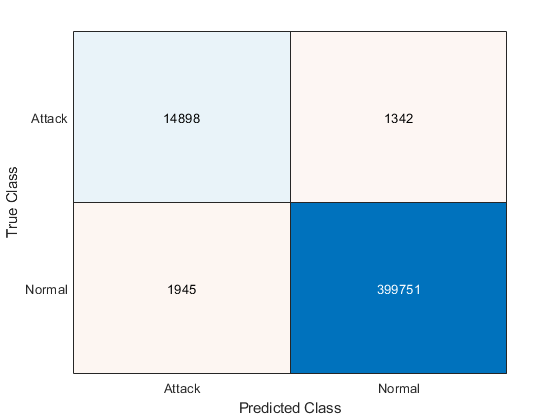

    'FIT101Range', 'FIT101Peaks','AIT201Filtered','AIT202SmoothDetrend', 'AIT202Minima', 'AIT202Maxima', 'AIT202PeakRange','AIT203Smoothed', ...
    'AIT203Minima', 'AIT203Maxima','FIT201', 'FIT201Maxima', 'FIT201Range','FIT301Smoothed', 'FIT301Maxima', 'FIT301Range','LIT301Smoothed', ...
    'LIT301Maxima', 'LIT301Minima', 'LIT301Range', 'LIT301Slopes','AIT401Processed','AIT401Smoothed','FIT401Smoothed','LIT401Smoothed', ...

    'LIT401Maxima', 'LIT401Minima', 'LIT401Range', 'LIT401Slopes','P403AIT501Smoothed','AIT502Smoothed','AIT503Smoothed','AIT504Smoothed','P501', ...
   'PIT502Smoothed','FIT601','P602','Normal_Attack'});

### Feature scaling

dfScaled = zscore(dfprocessed);

Unrecognized function or variable 'dfprocessed'.

### PCA

## Experiments

### Experiment 1 - Feature scaled vs original scale

### Histograms of sensor data

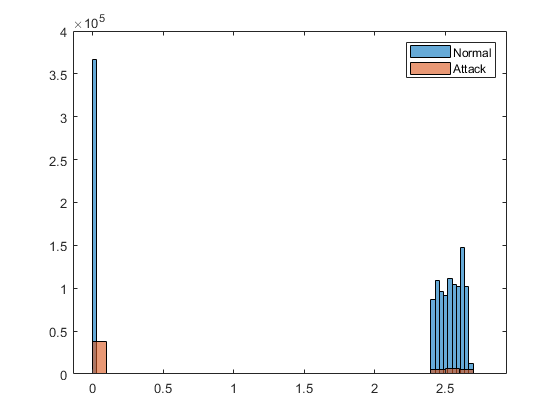

plotHist(df,2)